% Header

# Plotting

## Syntax 

Some selected MATLAB plotting commands are summarized here. There are a number of variations available through the online help. But this should get you started.

- `figure('color', 'w') `— creates a new figure with background color set to white.

- `plot(X,Y,LineSpec, ...) ` — sets the line style, marker symbol, and color.

- `plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn) ` — sets the line style, marker type, and color for each line.  

- `axis([xmin xmax ymin ymax])` — Set the *x*-axis limits to range from xmin to xmax. Set the *y*-axis limits to range from ymin to ymax.

- `xlim([xmin xmax]) | ylim([ymin ymax])`  — Sets the *x*-axis | y-axis limits for the current axes or chart.  

- `grid on` —  displays the major grid lines for the current axes or chart returned by the gca command. Major grid lines extend from each tick mark.

- `hold on`  —   retains plots in the current axes so that new plots added to the axes do not delete existing plots

- `hold off`  —   sets the hold state to off so that new plots added to the axes clear existing plots 

- `xlabel(txt, ...)` | `ylabel(txt, ...) `— labels the *x*-axis | y-axis of the current axes. txt can be character array or cell array

- `legend(label1,...,labelN, 'Location', 'Best')` —  sets the legend labels. Specify the labels as a list of character vectors or strings, such as legend('Jan','Feb','Mar', 'Location', 'Best').

- `legend(labels, 'Location', 'Best') `—  sets the labels using a cell array of character arrays such as legend({'Jan','Feb','Mar'}, 'Location', 'Best'). 

- `title(titletext, ...) `—  adds the specified title to the current figure

- `subplot(m,n,p)` divides the current figure into an m-by-n grid and creates axes in the position specified by p. MATLAB® numbers subplot positions by row. The first subplot is the first column of the first row, the second subplot is the second column of the first row, and so on. 

- `loglog(X,Y, LineSpec, ...)` plots x- and y-coordinates using a base 10 logarithmic scale on the x-axis and the y-axis.

- `semilogy(X,Y, LineSpec, ...)` plots x- and y-coordinates using a linear scale on the x-axis and a base-10 logarithmic scale on the y-axis.

- `text(x,y,txt, ....) `—  adds text description to one point, x and y. 

### `Housekeeping`

clc; clear; close all;

## 'Basic Plotting: Experimental Data

The following experimental data was collected on the current (I) in the positive direction and voltage (V) across the terminals of two different thermionic rectifiers. Create a proper plot of the data.

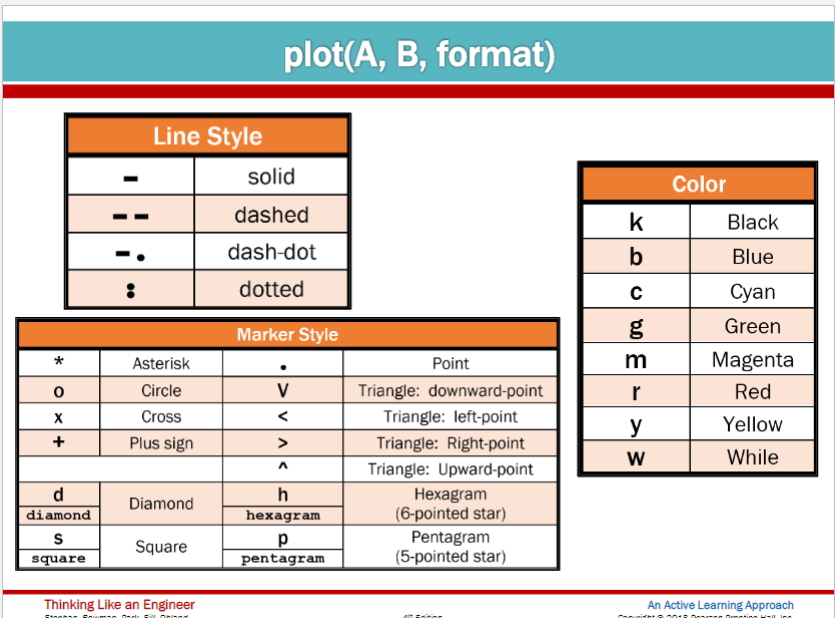

EVERY TIME YOU HAVE EXPERIMENTAL DATA DO DOTS

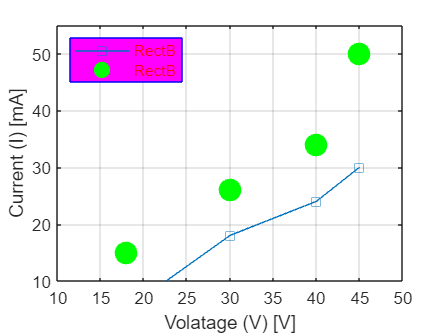

% Variables
Voltage=[18,30,40,45];	%[V]
RectA=[5,18,24,30];	%[mA]
RectB=[15,26,34,50];	%[mA]

% Create the graph
figure('Color','w')
plot(Voltage,RectA,'Marker','s');hold on;%adds two graphs on same plot
plot(Voltage,RectB,'og','MarkerFaceColor','g','MarkerSize',12)
% Add Proper Plot Elements
xlim([10 50])%min,max
ylim([10 55])%min,max
xticks([10:5:50])% min:increment:max
% Axis limits
grid on;
%or 
% grid minor
% Gridlines

% Axis labels
xlabel('Volatage (V) [V]')
ylabel('Current (I) [mA]')
% Legend
legend('RectB','RectB','Location','NW','TextColor','r','Color','m','EdgeColor','b')

## Basic Plotting: Theoretical Data

An environmental engineer has obtained a bacterial culture from a municipal water sample and allowed the bacteria to grow. After several hours of data collection, the following model is created.


$$B=B_0e^{kt}$$


Create a graph of the growth of the bacteria in number (B) versus time (t). Allow time to vary on the abscissa from 0 to 5 hours with an initial concentration of 10 bacteria. Model two growth constants (k) of 0.2 per hour and 0.3 per hour.

% Create theoretical data
% Set Constants
B_0=10;
K_1=0.2; %h^-1
K_2=0.3; %h^-1

% Create independent variable series [min:increment:max]
t=0:0.01:5;

% Create dependent variable series given the equation
B_1=B_0*exp(K_1*t)

B_1 =    10.0000   10.0200   10.0401   10.0602   10.0803   10.1005   10.1207   10.1410   10.1613   10.1816   10.2020   10.2224   10.2429   10.2634   10.2840   10.3045   10.3252   10.3458   10.3666   10.3873   10.4081   10.4289   10.4498   10.4707   10.4917   10.5127   10.5338   10.5548   10.5760   10.5971   10.6184   10.6396   10.6609   10.6823   10.7037   10.7251   10.7466   10.7681   10.7896   10.8112   10.8329   10.8546   10.8763   10.8981   10.9199   10.9417   10.9636   10.9856   11.0076   11.0296


B_2=B_0*exp(K_2*t)

B_2 =    10.0000   10.0300   10.0602   10.0904   10.1207   10.1511   10.1816   10.2122   10.2429   10.2737   10.3045   10.3355   10.3666   10.3977   10.4289   10.4603   10.4917   10.5232   10.5548   10.5866   10.6184   10.6503   10.6823   10.7144   10.7466   10.7788   10.8112   10.8437   10.8763   10.9090   10.9417   10.9746   11.0076   11.0407   11.0738   11.1071   11.1405   11.1739   11.2075   11.2412   11.2750   11.3088   11.3428   11.3769   11.4111   11.4454   11.4798   11.5142   11.5488   11.5835


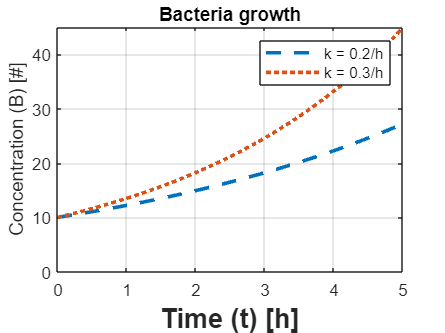


% Open a new figure window
figure();

% Create the graph
plot(t,B_1,'--','LineWidth',2); hold on;
plot(t,B_2,':','LineWidth',2)
    % or plot(t,B_1,t,b2)

% Add Proper Plot Elements
ylim([0 45])
% Axis limits

% Gridlines
grid on;
% Axis titles and legend names
AT={'Time (t) [h]' 'Concentration (B) [#]'};
LT={'k = 0.2/h' 'k = 0.3/h'};

% Axis labels
xlabel(AT{1},'FontSize',15,'FontWeight','bold')
ylabel(AT{2})
title("Bacteria growth")
% Legend
 legend(LT)

## Subplot

An engineer is conducting tests of two prototype toothbrush sanitizers that use ultraviolet radiation to kill pathogenic organisms while the toothbrush is stored. The engineer is trying to determine the minimum power needed to reliably kill pathogens on toothbrushes. Several toothbrushes are treated with a mix of bacteria, fungi, and viruses typically found in the human mouth, and then each is placed in one of the sanitizers for six hours at a specific power level (P). After six hours in the sanitizers, the number of viable pathogens remaining (R) on each toothbrush is assayed.

**basically** p**ut all windows together and then can index them**

**(total rows, total columns, number)**

clear
clc
close all

% Variables
% P = Power [W]
% R = Pathogens Remaining [%]
% A, B = Two Sanitizer types tested

% Enter experimental data
P = [10 18 25 40];	% [W]	
R1 = [46 35 14 2];	% [%]
R2 = [58 41 21 7];	% [%]
LT = {'Sanitizer A';'Sanitizer B'}	

LT = 2×1 cell array
    {'Sanitizer A'}
    {'Sanitizer B'}


c=[245 102 0;82 45 128]/255

c =     0.9608    0.4000         0
    0.3216    0.1765    0.5020


% Open a new figure window
figure('Color','w')
% Create the graph

% subplot(1,2,1);plot(P,R1)
% subplot(1,2,2);plot(P,R2)

r=[R1;R2]

r =     46    35    14     2
    58    41    21     7


m={'>','+'}

m = 1×2 cell array
    {'>'}    {'+'}


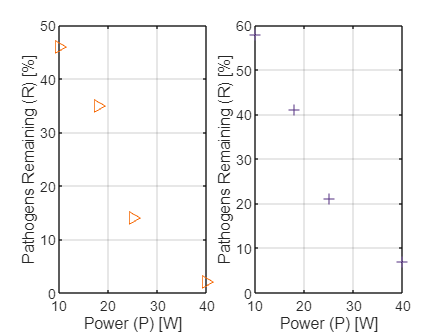

for plo=1:2
    subplot(1,2,plo);plot(P,r(plo,:),m{plo},'Color',c(plo,:))
    xlabel('Power (P) [W]');
    ylabel('Pathogens Remaining (R) [%]');
    grid on

end
% Add Proper Plot Elements

% Axis limits

% Gridlines

% Axis labels
xlabel('Power (P) [W]');
ylabel('Pathogens Remaining (R) [%]');



% Legend
 %legend(LT{1},LT{2})
 %or


## Log-log Plots

Graph volume and radius of a cylinder, holding height constant.

clear
clc
close all

% Variables
% R = radius [cm]
% V = volume, cylinder [cubic cm]
% v=pi*r^2*h
% Enter experimental data
R = [0.5 1 1.25 1.5 2];		% Radius [cm]
V = [3 13 20 28 50];		% Volume [cubic cm]

% Create graph of experimental data, with both axis shown as logarithmic
color=[1,0.5,0.7] %rgb, ranges from 0 to 1

color =     1.0000    0.5000    0.7000


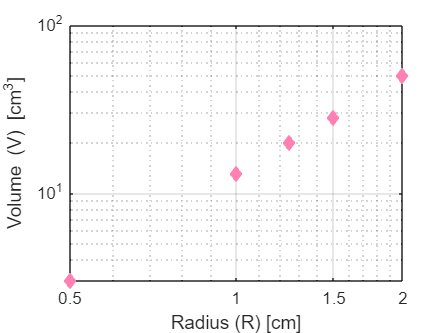

figure('Color','w')
loglog(R,V,'d','Color',color,'MarkerFaceColor',color)
grid minor; % required for log finctions
xlabel('Radius (R) [cm]')
ylabel('Volume (V) [cm^3]')


%wanna put in greek letters, go to greek letters and doc, like\alpha

## Semilog Plots

Graph the voltage in a capacitor over time holding initial voltage ($V_0$), capacitance (C), and resistance (R) constant.

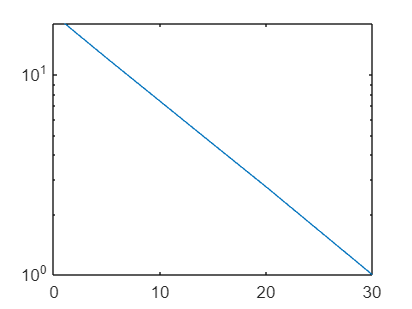

clear
clc
close all

% Variables
% t = time [s]
% V = voltage [V]

% Enter experimental data
t = [1 5 15 20 30];		% time [s]
V = [18.1 12.1 4.5 2.75 1];	% voltage [V]

% Create graph of experimental data with the ordinate as logarithmic

semilogy(t,V); % when have linear line, slope is linear and can help 

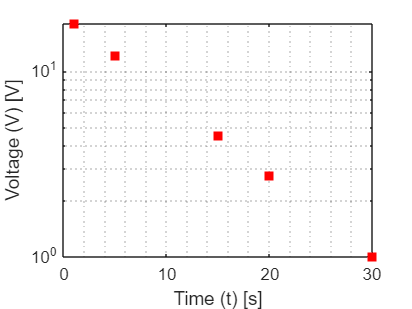

% with finding exponential and other important things, if u fit a
% linear model to something, you get the y=be^(mx), fits model to data
figure()
semilogy(t,V,'sr','MarkerFaceColor','r')

xlabel('Time (t) [s]')
ylabel('Voltage (V) [V]')

grid minor;